## Estudiantes:

- Juan Valverde Campos B47200

- Lucía Sanahuja Vindas B36401

- Jose Pablo Mora Villalobos B85326

- Marco Ferraro Rodríguez B82957

## Pregunta # 1  

format shortE 
[n , xmin , xmax , listaElementos] = FPSet(10,2,2) ;
fprintf('La cantidad de elementos son %3i\n ',n);

La cantidad de elementos son 901
 

fprintf('El Xmin es de  %1.1e\n ',xmin);

El Xmin es de  1.0e-02
 

fprintf('El Xmax es de  %1.1e\n ',xmax);

El Xmax es de  9.9e+02
 

fprintf('Los elementos son');

Los elementos son

 disp(listaElementos);

  Columns 1 through 6
   1.0000e-02   1.0000e-01   1.0000e+00   1.0000e+01   1.0000e+02   1.1000e-02
  Columns 7 through 12
   1.1000e-01   1.1000e+00   1.1000e+01   1.1000e+02   1.2000e-02   1.2000e-01
  Columns 13 through 18
   1.2000e+00   1.2000e+01   1.2000e+02   1.3000e-02   1.3000e-01   1.3000e+00
  Columns 19 through 24
   1.3000e+01   1.3000e+02   1.4000e-02   1.4000e-01   1.4000e+00   1.4000e+01
  Columns 25 through 30
   1.4000e+02   1.5000e-02   1.5000e-01   1.5000e+00   1.5000e+01   1.5000e+02
  Columns 31 through 36
   1.6000e-02   1.6000e-01   1.6000e+00   1.6000e+01   1.6000e+02   1.7000e-02
  Columns 37 through 42
   1.7000e-01   1.7000e+00   1.7000e+01   1.7000e+02   1.8000e-02   1.8000e-01
  Columns 43 through 48
   1.8000e+00   1.8000e+01   1.8000e+02   1.9000e-02   1.9000e-01   1.9000e+00
  Columns 49 through 54
   1.9000e+01   1.9000e+02   2.0000e-02   2.0000e-01   2.0000e+00   2.0000e+01
  Columns 55 through 60
   2.0000e+02   2.1000e-02   2.1000e-01   2.1000e+00

***Nota : Dado que el 0 no es positivo no se incluye en el resultado***

## Pregunta #3

format short
f = @(x) (667.38/x) * (1-exp(-x*10/68.1)) - 40;
y = 0;
fplot(f,[12,17])

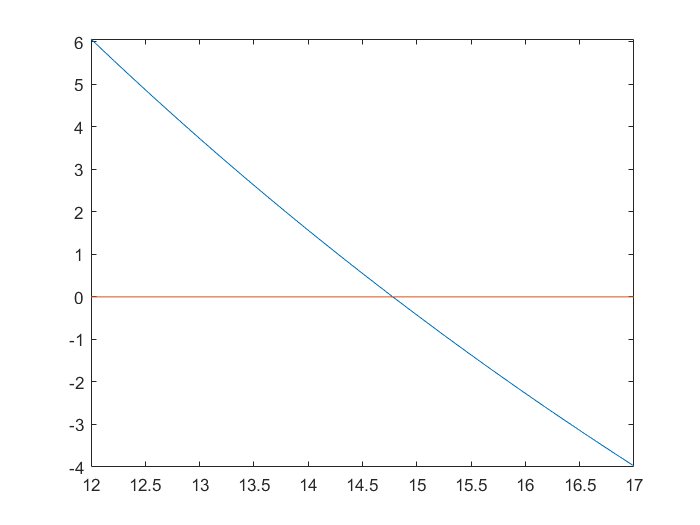

hold on
fplot(y,[12,17])
hold off

iterMax =  floor( log2( ( 15 - 14) / (0.005 ) ) ) + 1;
biseccionT2(f, 14, 15, 0.005, iterMax);

    Iter     a         b         x          f(x)      error
    1.0000   14.0000   15.0000   14.5000    0.5523    1.0000
    2.0000   14.5000   15.0000   14.7500    0.0590    0.5000
    3.0000   14.7500   15.0000   14.8750   -0.1841    0.2500
    4.0000   14.7500   14.8750   14.8125   -0.0629    0.1250
    5.0000   14.7500   14.8125   14.7812   -0.0020    0.0625
    6.0000   14.7500   14.7812   14.7656    0.0284    0.0312
    7.0000   14.7656   14.7812   14.7734    0.0132    0.0156
    8.0000   14.7734   14.7812   14.7773    0.0056    0.0078
    9.0000   14.7773   14.7812   14.7793    0.0018    0.0039


## Funciones

### Función para realizar pregunta #1

function[n,xmin,xmax,listaElementos] = FPSet(b, t, u)
% INPUT: b, t, u
% DESCRIPCIÓN : Se obtiene una lista con los elementos positivos del conjunto F
% OUTPUT: n (Cantidad de elementos) ,xmin (El menor número en positivo),xmax (El mayor número positivo),listaElementos (Elementos positivos del conjunto F)
 
    n = 2*(b-1) * b^(t-1) * (u--u+1) + 1;
    xmin = b ^ -u;
    xmax = (1 - b^(-t) ) * b^(u+1);
    iteracion = 1;
    aumento = b ^(-(t-1)) ;
    finalizacion = b - aumento;
    listaElementos = zeros(1,(n-1)/2 );
    for k =  1 : aumento : finalizacion
        for j = -u : 1 : u
            listaElementos(iteracion) = k * b^(j);
            iteracion = iteracion + 1 ;
        end
    end
end

### Función para realizar pregunta #3

function [T] = biseccionT2(f, a, b, tol, iterMax)
%Input:f, a, b, tol, iterMax; Output: Matriz
%DESCRIPCIÓN : Almacena los resultados de una iteración por el método de la bisección.
%T(k,:) = [k a b x f(x) err]

% Verificar si se cumple la condición de cambio de signo
    if f(a) * f(b) > 0
        disp('No se cumple el cambio de signo!')
        return %abandonar la función
    end
    k = 1;
    w = ( a + b ) / 2;
    err = abs( b - a );
    T(k,:) = [k a b w f(w) err];
    
    while k < iterMax+1 && err >= tol
        % Determinar el valor de x y actualizar el intervalo
        if f(a) * f(w) < 0
            b = w;
        else
            a = w;
        end
        % Preparar las siguiente iteración
        err = abs( b - a );
        k = k + 1;
        % Matriz que almacena los resultados de cada iteración.
        w=(a+b)/2;
        T(k,:) = [k a b w f(w) err];
    end
    names = ['    Iter     a         b         x          f(x)      error'];
    disp(names)
    disp(T)
end